# Lab - Root Finding 1 - Bracketing

**Topics: **Bisection & fzero

## Root finding 

clear, clc, format compact

### Set up the problem

Determine the mass, *m*, of the bungee jumper with a drag coefficient, $c_d$, of 0.25 to have a velocity of 36 [m/s] after 4 [s] of free fall. The acceleration of gravity, *g*, in SI units is 9.81 [m/s/s]. Given the following function:


$$v\left(t\right)=\sqrt{\frac{\mathrm{gm}}{c_d }}\tanh \left(\sqrt{\frac{{\mathrm{gc}}_d }{m}}t\right)$$


dragCoeff = 0.25;
velocity = 36;
time = 4;
gravity = 9.81;

f =  @(m) sqrt(gravity*m/dragCoeff).*tanh(sqrt(gravity*dragCoeff./m)*time) - velocity;

### Find the bounds that contain the root

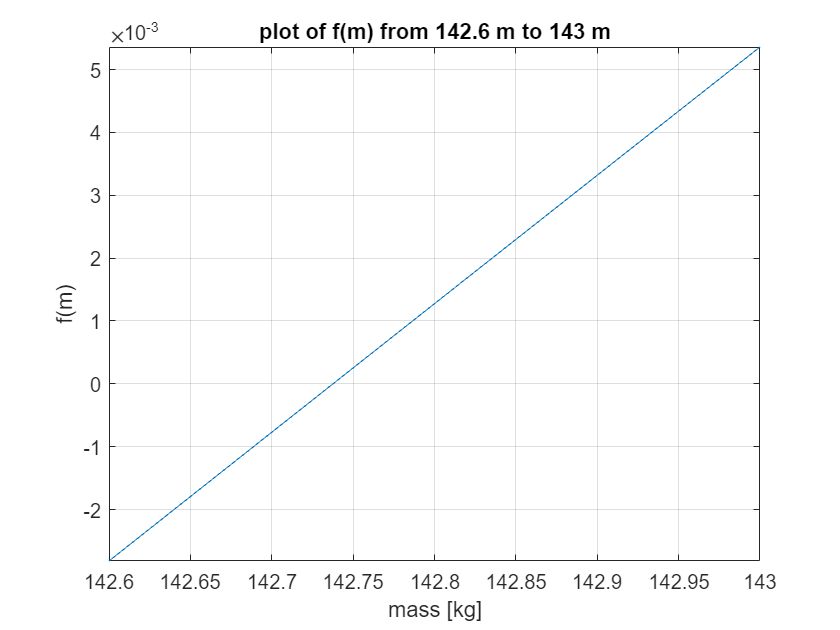

fplot(f,[142.6,143])
title('plot of f(m) from 142.6 m to 143 m')
xlabel('mass [kg]')
ylabel('f(m)')
grid on;

### The root using bisection

m1 = bisect(f,140,145);
fprintf(['Using the bisect function \nthe mass of the bungee jumper is %8.4f kg\n'], m1)

Using the bisect function 
the mass of the bungee jumper is 142.7377 kg


### The root using fzero

m2 = fzero(f,145);
fprintf(['Using Matlab''s fzero function\nthe mass of the bungee jumper is %8.4f kg\n'], m2)

Using Matlab's fzero function
the mass of the bungee jumper is 142.7376 kg


### Verify the roots

f(m1),f(m2)

ans = 4.6089e-07

ans = 0